# Projecting functions

n_points = 101;

lo_bound = -pi;
hi_bound = pi;

dx = (hi_bound - lo_bound) / (n_points - 1); % n points, n-1 intervals

base = linspace(lo_bound, hi_bound, n_points)'; 
base

base =    -3.1416
   -3.0788
   -3.0159
   -2.9531
   -2.8903
   -2.8274
   -2.7646
   -2.7018
   -2.6389
   -2.5761


% set up input vectors; in this case 1, x, x^2, ..., x^5
n_deg = 6; % degrees 0 to 5. 6 different degrees.
V = zeros(n_points, n_deg, 'double');

for ii = 1:n_deg
    V(:, ii) = base .^ (ii-1);
end

## Gram-Schmidt to orthonormalize functions

W = gram_schmidt(V, dx);
W

W =     0.5745   -0.9852    1.2470   -1.4323    1.5609   -1.6423
    0.5745   -0.9655    1.1722   -1.2604    1.2488   -1.1496
    0.5745   -0.9458    1.0989   -1.0972    0.9649   -0.7266
    0.5745   -0.9261    1.0271   -0.9425    0.7082   -0.3676
    0.5745   -0.9064    0.9568   -0.7962    0.4771   -0.0671
    0.5745   -0.8867    0.8880   -0.6579    0.2704    0.1800
    0.5745   -0.8670    0.8207   -0.5277    0.0869    0.3786
    0.5745   -0.8473    0.7550   -0.4053   -0.0747    0.5333
    0.5745   -0.8276    0.6908   -0.2904   -0.2156    0.6487
    0.5745   -0.8079    0.6280   -0.1830   -0.3371    0.7289


vec_to_approx = sin(base)

vec_to_approx =    -0.0000
   -0.0628
   -0.1253
   -0.1874
   -0.2487
   -0.3090
   -0.3681
   -0.4258
   -0.4818
   -0.5358


a = zeros(1, n_deg); % a is a row vector holding scaling values 

for ii = 1:n_deg
    a(:, ii) = func_inner_prod(vec_to_approx, W(:, ii), dx)...
        /func_inner_prod(W(:, ii), W(:, ii), dx);
end
    
a

a =     0.0000    0.9405    0.0000   -0.7753    0.0000    0.1197


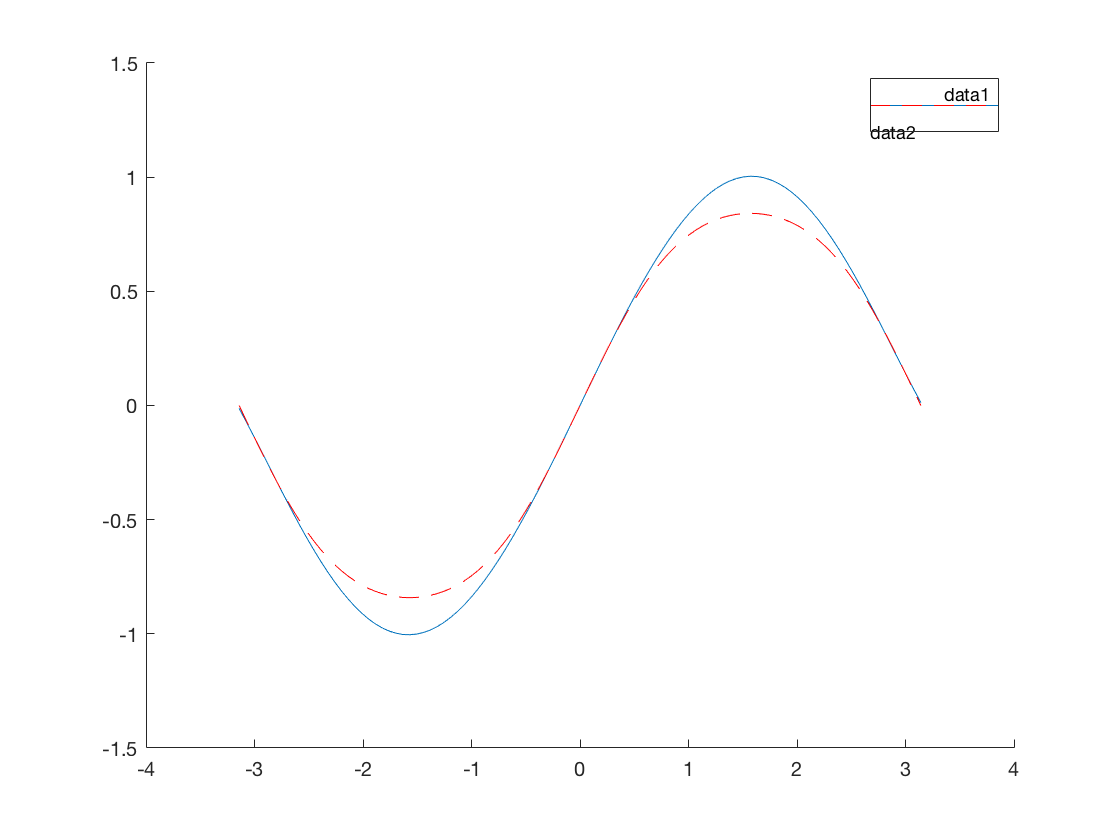

% This following code snippet verifies that gram schmidt works with
% functions - norm = 1 and inner project = 0 for different bases
%
% for ii = 1:n_deg
%     fprintf('Vector %d norm is\n', ii);
%     func_inner_prod(W(:, ii), W(:, ii), dx)
%     for jj = ii+1:n_deg
%         fprintf('>>> Inner product with %d\n', jj);
%         func_inner_prod(W(:, ii), W(:, jj), dx)
%     end
% end

reconstructed = sum(W .* a, 2); % sum across rows
taylor_approx = vec_to_approx - vec_to_approx .^ 3 / factorial(3)...
    + vec_to_approx .^ 5 / factorial(5);

figure;hold on
plot(base, reconstructed); label1 = 'orthonormal bases';
plot(base, taylor_approx, 'r--'); label2 = 'Taylor Approx';

function [inner_prod] = func_inner_prod(f, g, dx)
%FUNC_INNER_PROD approximates the inner product between two functions
    inner_prod = (f' * g) * dx;
end

function [U] = gram_schmidt(V, dx)
% The vectors v1, ..., vk (columns of matrix V, so that V(:,j) is the jth 
% vector) are replaced by orthonormal vectors (columns of U) which span the
% same subspace
    n = size(V,1); % dimension of each vector
    k = size(V,2); % number of vectors
    
    U = zeros(n,k);
    
    % normalize the first vector
    U(:,1) = V(:,1)/sqrt(func_inner_prod(V(:,1), V(:,1), dx)); 
    for i = 2:k
      U(:,i) = V(:,i);
      for j = 1:i-1
        U(:,i) = U(:,i) - func_inner_prod(U(:,i), U(:,j), dx)...
            / func_inner_prod(U(:,j), U(:,j), dx)...
            * U(:,j);      
      end
      % normalize after projection onto other bases
      U(:,i) = U(:,i)/sqrt(func_inner_prod(U(:,i), U(:,i), dx)); 
    end
end